# Beamforming Methods Sandbox

Switch between perturb_method_v24 (optimized ordinary perturbative) and perturb_method_constrained_v2 (optimized constrained), then run the same diagnostics on either. Tilt analysis is available for both methods. The last section benchmarks the apples-to-apples cost of findpeaks_circular vs findpeaks_fast (all other optimizations identical).

## Setup

clear
clc

freq   = 3e9;
lambda = 3e8 / freq;

phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];

## Geometry: 9-element regular ring

N  = 9;
d1 = 0.04880;
d2 = 0.04880;
[x, y] = d1d2Convert(d1, d2, N);

## Choose method & peak finder

method: "v24" (optimized ordinary) or "constrained" (optimized constrained_v2). fast_peaks: true uses findpeaks_fast, false uses findpeaks_circular.

method     = "v24";        % "v24" or "constrained"
fast_peaks = true;          % true = findpeaks_fast, false = findpeaks_circular

Max_iter         = 200;
eps_dB           = -20;
phi_0            = deg2rad(180);
cone_rad         = deg2rad(30);
max_outer_passes = 50;   % upper cap; outer loop early-exits when converged

## Run the selected method

Found 3 initial sidelobes above -20.0 dB.
iter = 0
After Iteration 1: 2 sidelobes above -20.0 dB
iter = 1
After Iteration 2: 4 sidelobes above -20.0 dB
iter = 2
After Iteration 3: 2 sidelobes above -20.0 dB
iter = 3
After Iteration 4: 2 sidelobes above -20.0 dB
iter = 4
After Iteration 5: 0 sidelobes above -20.0 dB


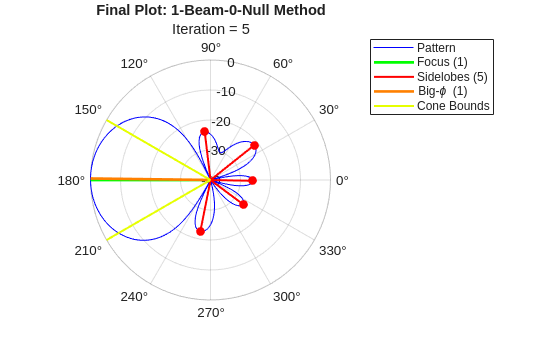

v24 (fast_peaks=1):  iters=5  final max sidelobe=NaN dB  time=7.557s


switch lower(method)
    case "v24"
        results = perturb_method_v24(Max_iter, eps_dB, x, y, phi_0, ...
            'cone_rad',        cone_rad, ...
            'fast_peaks',      fast_peaks, ...
            'verbose',         true, ...
            'show_final_plot', true, ...
            'return_funcs',    true);

        fprintf('v24 (fast_peaks=%d):  iters=%d  final max sidelobe=%.2f dB  time=%.3fs\n', ...
            fast_peaks, results.final_iteration, ...
            results.max_sidelobe_store(results.final_iteration+1), ...
            results.total_time);

    case "constrained"
        results = perturb_method_constrained_v2(Max_iter, eps_dB, x, y, phi_0, ...
            'cone_rad',         cone_rad, ...
            'max_outer_passes', max_outer_passes, ...
            'fast_peaks',       fast_peaks, ...
            'verbose',          true, ...
            'show_final_plot',  true, ...
            'return_funcs',     true);

        fprintf(['constrained (fast_peaks=%d):  L=%d  passes=%d  iters=%d  ' ...
                 'final dense-max sidelobe=%.2f dB  converged=%d  time=%.3fs\n'], ...
            fast_peaks, results.L, results.num_passes, results.final_iteration, ...
            results.dense_max_sidelobe_store(results.final_iteration+1), ...
            results.overall_converged, results.total_time);

    otherwise
        error('Unknown method "%s". Use "v24" or "constrained".', method);
end

## Sidelobe descent

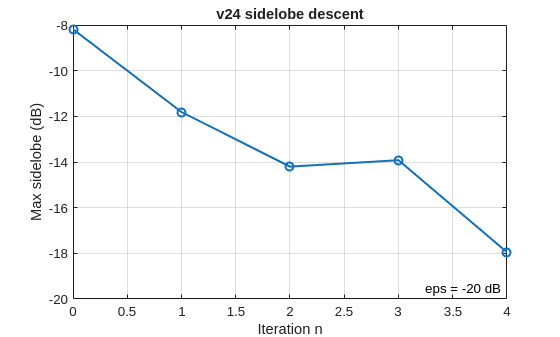

if method == "constrained"
    nIter = results.final_iteration;
    n     = (0:nIter).';

    figure;
    yyaxis left
    plot(n, results.dense_max_sidelobe_store(1:nIter+1), '-o', 'LineWidth', 1.5);
    hold on
    plot(n, results.max_sidelobe_store(1:nIter+1),       '--', 'LineWidth', 1.0);
    yline(eps_dB, ':k', sprintf('eps = %.0f dB', eps_dB));
    ylabel('Sidelobe (dB)');
    ylim([eps_dB - 10, 0]);

    yyaxis right
    plot(n, results.focus_value_store(1:nIter+1), '-s', 'LineWidth', 1.5);
    ylabel('|f_n(\phi_0)|');
    yline(results.L, '--', 'L', 'LabelHorizontalAlignment', 'left');

    for k = 2:numel(results.pass_start_iter)
        xline(results.pass_start_iter(k) - 1, ':', sprintf('pass %d', k));
    end

    xlabel('Iteration n');
    title('Constrained: dense-mesh + sample-set sidelobe descent');
    legend({'dense-mesh max', 'sample-set max', 'eps', '|f(\phi_0)|', 'L'}, ...
           'Location', 'best');
    grid on;
else
    nIter = results.final_iteration;
    n     = (0:nIter).';
    figure;
    plot(n, results.max_sidelobe_store(1:nIter+1), '-o', 'LineWidth', 1.5);
    yline(eps_dB, ':k', sprintf('eps = %.0f dB', eps_dB));
    xlabel('Iteration n'); ylabel('Max sidelobe (dB)');
    title('v24 sidelobe descent'); grid on;
end

## Per-pass energy decay (constrained-only)

if method == "constrained"
    figure; hold on
    colors = lines(results.num_passes);
    coef_K = results.coef_K_phi0;

    for p = 1:results.num_passes
        n_start = results.pass_start_iter(p);
        if p < numel(results.pass_start_iter)
            n_end = results.pass_start_iter(p+1);
        else
            n_end = results.final_iteration + 1;
        end
        if n_end < n_start, continue; end

        rng_idx = n_start:n_end;
        A_cells = results.A_eff_store(rng_idx);
        h_star  = results.pass_coef_hstar{p};

        dist_p  = cellfun(@(c) norm((c - coef_K) - h_star), A_cells).';
        qp      = results.pass_q_rate_upper(p);
        k_local = (0:numel(rng_idx)-1).';
        bnd_p   = qp.^k_local .* dist_p(1);

        semilogy(k_local, max(dist_p, eps), '-o', 'Color', colors(p,:), 'LineWidth', 1.5);
        semilogy(k_local, max(bnd_p,  eps), '--', 'Color', colors(p,:), 'LineWidth', 1.0);
    end

    set(gca, 'YScale', 'log');
    xlabel('Iteration within pass');
    ylabel('||h_n - h^*_{pass}||');
    title('Per-pass energy decay vs. theoretical envelope');
    grid on;
    legend(arrayfun(@(p) sprintf('pass %d', p), 1:results.num_passes, ...
                    'UniformOutput', false), 'Location', 'best');
end

## Final basis-function coefficients

c = results.A_eff;

fprintf('\n  j      Re(c_j)        Im(c_j)        |c_j|       arg(c_j) [deg]\n');


  j      Re(c_j)        Im(c_j)        |c_j|       arg(c_j) [deg]


fprintf(  '  -----------------------------------------------------------------\n');

  -----------------------------------------------------------------


for j = 1:numel(c)
    fprintf('  %2d   %+12.6f   %+12.6f   %10.6f   %+10.4f\n', ...
            j, real(c(j)), imag(c(j)), abs(c(j)), rad2deg(angle(c(j))));
end

   1      +0.732596      +0.000000     0.732596      +0.0000
   2      -0.520551      +0.622995     0.811848    +129.8808
   3      +0.488755      -0.009548     0.488848      -1.1192
   4      -0.520551      -0.622995     0.811848    -129.8808
   5      +0.488755      +0.009548     0.488848      +1.1192
   6      -0.356166      +0.968433     1.031852    +110.1923
   7      -0.435055      -0.962224     1.056006    -114.3294
   8      -0.356166      -0.968433     1.031852    -110.1923
   9      -0.435055      +0.962224     1.056006    +114.3294


fprintf('\n');

## Method comparison: v24 vs constrained (polar superposition)

Runs both methods with identical Max_iter, eps_dB, x, y, phi_0, cone_rad and superimposes their final patterns on a single polar plot. BOTH patterns are normalized to the constrained method's peak (the reference), so the v24 curve shows its true magnitude relative to constrained. Clipped at -40 dB. Legend sits above the plot in the title strip so it never covers any data.

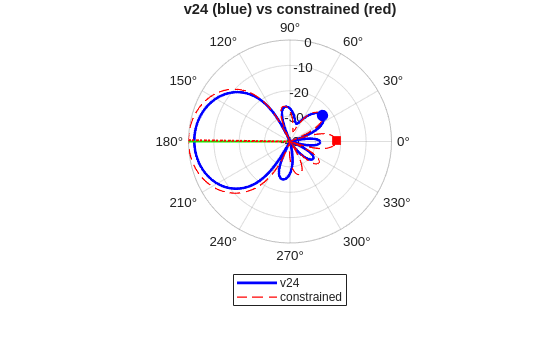

% Run v24 (ordinary perturbative)
res_v24 = perturb_method_v24(Max_iter, eps_dB, x, y, phi_0, ...
    'cone_rad',        cone_rad, ...
    'fast_peaks',      fast_peaks, ...
    'verbose',         false, ...
    'show_final_plot', false, ...
    'return_funcs',    false);

% Run constrained
res_con = perturb_method_constrained_v2(Max_iter, eps_dB, x, y, phi_0, ...
    'cone_rad',         cone_rad, ...
    'max_outer_passes', max_outer_passes, ...
    'fast_peaks',       fast_peaks, ...
    'verbose',          false, ...
    'show_final_plot',  false, ...
    'return_funcs',     false);

clip_dB_overlay = -40;

F_v24 = res_v24.final_function;
F_con = res_con.final_function;

% Common reference: peak of the constrained pattern. Both curves are
% normalized against THIS peak.
peak_ref  = max(abs(F_con));
to_dB_ref = @(F) max(10*log10(abs(F).^2 / peak_ref^2), clip_dB_overlay);

% Per-pattern statistics (all in dB relative to the constrained peak)
[v24_max_val, v24_max_idx] = max(abs(F_v24));
[con_max_val, con_max_idx] = max(abs(F_con));
v24_max_phi = phi_mesh(v24_max_idx);
con_max_phi = phi_mesh(con_max_idx);
v24_max_dB  = 20*log10(v24_max_val / peak_ref);
con_max_dB  = 20*log10(con_max_val / peak_ref);   % = 0 by construction

% Field at the intended direction phi_0
F_v24_phi0  = abs(interp1(phi_mesh, F_v24, phi_0, 'linear','extrap'));
F_con_phi0  = abs(interp1(phi_mesh, F_con, phi_0, 'linear','extrap'));
v24_phi0_dB = 20*log10(F_v24_phi0 / peak_ref);
con_phi0_dB = 20*log10(F_con_phi0 / peak_ref);

% Worst sidelobe (largest peak excluding main beam) for each pattern
[pv_v, pl_v] = findpeaks_fast(abs(F_v24), phi_mesh);
[~, im_v] = min(abs(atan2(sin(pl_v - phi_0), cos(pl_v - phi_0))));
pv_v(im_v) = []; pl_v(im_v) = [];
[v24_sl_val, isl_v] = max(pv_v);
v24_sl_phi = pl_v(isl_v);
v24_sl_dB  = 20*log10(v24_sl_val / peak_ref);

[pv_c, pl_c] = findpeaks_fast(abs(F_con), phi_mesh);
[~, im_c] = min(abs(atan2(sin(pl_c - phi_0), cos(pl_c - phi_0))));
pv_c(im_c) = []; pl_c(im_c) = [];
[con_sl_val, isl_c] = max(pv_c);
con_sl_phi = pl_c(isl_c);
con_sl_dB  = 20*log10(con_sl_val / peak_ref);

t_v24 = res_v24.total_time;
t_con = res_con.total_time;

% rel-err: relative L2 norm of the magnitude difference between the two
% patterns, using the constrained pattern as the reference, i.e.
%     rel-err = ||  |F_v24| - |F_con|  ||_2  /  || |F_con| ||_2
% A single-number "are these the same shape?" diagnostic. Near 0 means the
% two patterns agree pointwise across the dense phi mesh; larger values
% mean they diverge somewhere notable. It is holistic (not directional);
% the polar plot itself shows WHERE they differ.
err_methods = norm(abs(F_v24) - abs(F_con)) / norm(abs(F_con));

% ---- Polar plot (minimal annotations; numeric breakdown is in the next panel) ----
figure('Name','v24 vs constrained');
polarplot(phi_mesh, to_dB_ref(F_v24), 'b-',  'LineWidth', 2.0); hold on;
polarplot(phi_mesh, to_dB_ref(F_con), 'r--', 'LineWidth', 1.0);
rlim([clip_dB_overlay 0]);

% Radial guide lines: intended phi_0 (green), each pattern's actual peak angle (dotted, color-matched)
polarplot([phi_0       phi_0      ], [clip_dB_overlay 0],                                        'g-', 'LineWidth', 1.5);
polarplot([v24_max_phi v24_max_phi], [clip_dB_overlay max(v24_max_dB, clip_dB_overlay)],         'b:', 'LineWidth', 1.5);
polarplot([con_max_phi con_max_phi], [clip_dB_overlay max(con_max_dB, clip_dB_overlay)],         'r:', 'LineWidth', 1.5);

% Worst-sidelobe markers (no on-plot text labels — values are in the next panel)
polarplot(v24_sl_phi, max(v24_sl_dB, clip_dB_overlay), 'bo', 'MarkerFaceColor','b', 'MarkerSize',8);
polarplot(con_sl_phi, max(con_sl_dB, clip_dB_overlay), 'rs', 'MarkerFaceColor','r', 'MarkerSize',8);

title('v24 (blue) vs constrained (red)');
legend({'v24','constrained'}, 'Location','southoutside');

## Tilt Analysis

Max tilt with WS <= -20 dB:  yz = 14.17 deg,  x-dir = 12.14 deg.


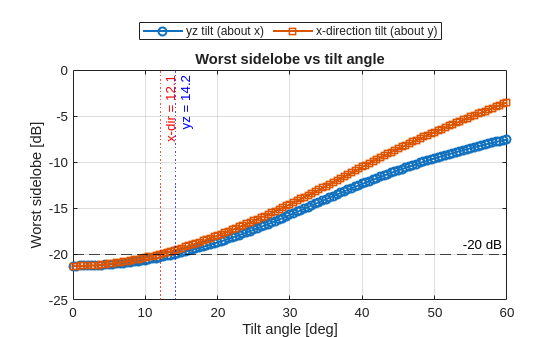

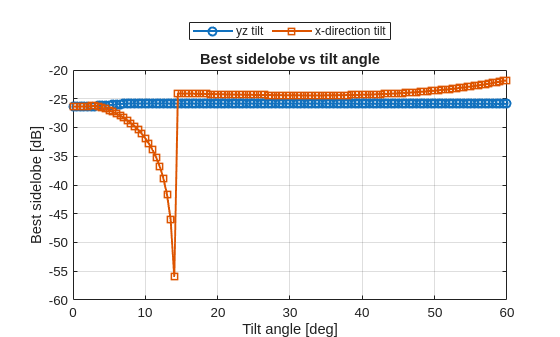

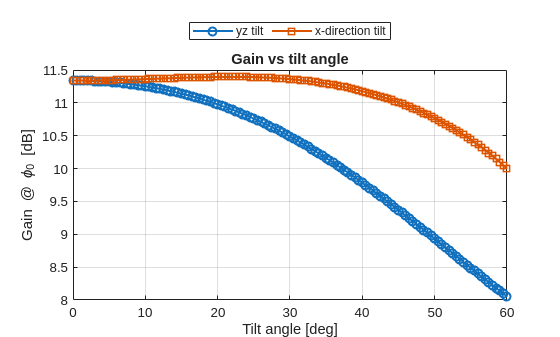


tilt_threshold_dB = -20;
tilt_angles_deg   = linspace(0, 60, 121);

tilt_v24 = tilt_analysis( ...
    'method',         'v24', ...
    'N',              N, ...
    'd_ideal',        d1, ...
    'phi_0',          phi_0, ...
    'Max_iter',       Max_iter, ...
    'eps_dB',         eps_dB, ...
    'threshold_dB',   tilt_threshold_dB, ...
    'angle_deg_list', tilt_angles_deg, ...
    'verbose',        false);

Max tilt with WS <= -20 dB:  yz = 19.93 deg,  x-dir = 18.47 deg.


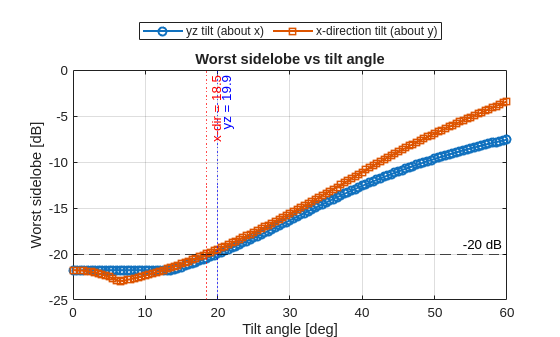

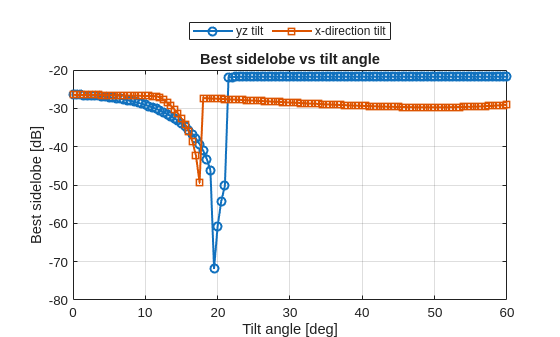

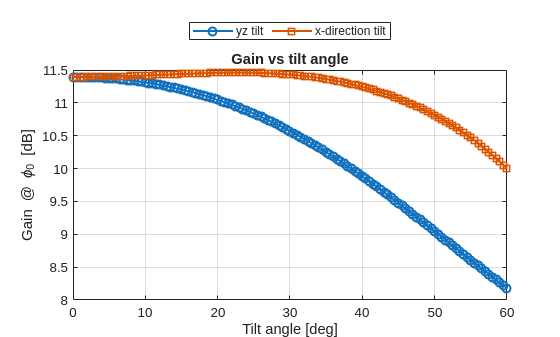


tilt_constrained = tilt_analysis( ...
    'method',           'constrained', ...
    'N',                N, ...
    'd_ideal',          d1, ...
    'phi_0',            phi_0, ...
    'Max_iter',         Max_iter, ...
    'eps_dB',           eps_dB, ...
    'threshold_dB',     tilt_threshold_dB, ...
    'cone_rad',         cone_rad, ...
    'max_outer_passes', max_outer_passes, ...
    'angle_deg_list',   tilt_angles_deg, ...
    'verbose',          false);

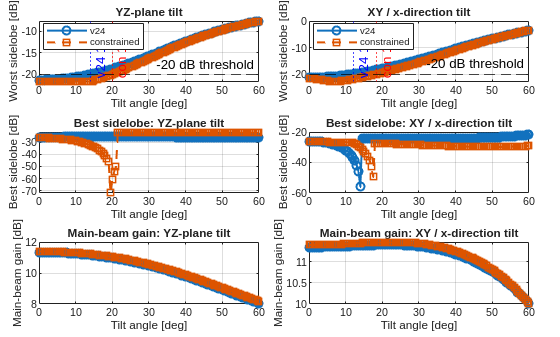


figure('Name', 'Tilt comparison: v24 vs constrained', 'Color', 'w');
tiledlayout(3, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
plot(tilt_v24.angle_deg_list, tilt_v24.worst_yz, '-o', 'LineWidth', 1.5);
hold on;
plot(tilt_constrained.angle_deg_list, tilt_constrained.worst_yz, '--s', 'LineWidth', 1.5);
yline(tilt_threshold_dB, 'k--', sprintf('%.0f dB threshold', tilt_threshold_dB));

if ~isnan(tilt_v24.max_tilt_yz_deg)
    xline(tilt_v24.max_tilt_yz_deg, 'b:', ...
        sprintf('v24 %.1f', tilt_v24.max_tilt_yz_deg));
end

if ~isnan(tilt_constrained.max_tilt_yz_deg)
    xline(tilt_constrained.max_tilt_yz_deg, 'r:', ...
        sprintf('con %.1f', tilt_constrained.max_tilt_yz_deg));
end

grid on;
xlabel('Tilt angle [deg]');
ylabel('Worst sidelobe [dB]');
title('YZ-plane tilt');
legend({'v24', 'constrained'}, 'Location', 'best');

nexttile;
plot(tilt_v24.angle_deg_list, tilt_v24.worst_xz, '-o', 'LineWidth', 1.5);
hold on;
plot(tilt_constrained.angle_deg_list, tilt_constrained.worst_xz, '--s', 'LineWidth', 1.5);
yline(tilt_threshold_dB, 'k--', sprintf('%.0f dB threshold', tilt_threshold_dB));

if ~isnan(tilt_v24.max_tilt_xz_deg)
    xline(tilt_v24.max_tilt_xz_deg, 'b:', ...
        sprintf('v24 %.1f', tilt_v24.max_tilt_xz_deg));
end

if ~isnan(tilt_constrained.max_tilt_xz_deg)
    xline(tilt_constrained.max_tilt_xz_deg, 'r:', ...
        sprintf('con %.1f', tilt_constrained.max_tilt_xz_deg));
end

grid on;
xlabel('Tilt angle [deg]');
ylabel('Worst sidelobe [dB]');
title('XY / x-direction tilt');
legend({'v24', 'constrained'}, 'Location', 'best');

nexttile;
plot(tilt_v24.angle_deg_list, tilt_v24.best_yz, '-o', 'LineWidth', 1.5);
hold on;
plot(tilt_constrained.angle_deg_list, tilt_constrained.best_yz, '--s', 'LineWidth', 1.5);
grid on;
xlabel('Tilt angle [deg]');
ylabel('Best sidelobe [dB]');
title('Best sidelobe: YZ-plane tilt');

nexttile;
plot(tilt_v24.angle_deg_list, tilt_v24.best_xz, '-o', 'LineWidth', 1.5);
hold on;
plot(tilt_constrained.angle_deg_list, tilt_constrained.best_xz, '--s', 'LineWidth', 1.5);
grid on;
xlabel('Tilt angle [deg]');
ylabel('Best sidelobe [dB]');
title('Best sidelobe: XY / x-direction tilt');

nexttile;
plot(tilt_v24.angle_deg_list, tilt_v24.gain_yz, '-o', 'LineWidth', 1.5);
hold on;
plot(tilt_constrained.angle_deg_list, tilt_constrained.gain_yz, '--s', 'LineWidth', 1.5);
grid on;
xlabel('Tilt angle [deg]');
ylabel('Main-beam gain [dB]');
title('Main-beam gain: YZ-plane tilt');

nexttile;
plot(tilt_v24.angle_deg_list, tilt_v24.gain_xz, '-o', 'LineWidth', 1.5);
hold on;
plot(tilt_constrained.angle_deg_list, tilt_constrained.gain_xz, '--s', 'LineWidth', 1.5);
grid on;
xlabel('Tilt angle [deg]');
ylabel('Main-beam gain [dB]');
title('Main-beam gain: XY / x-direction tilt');


fprintf('\nTilt summary (worst sidelobe threshold = %.0f dB):\n', tilt_threshold_dB);


Tilt summary (worst sidelobe threshold = -20 dB):



fprintf('  v24:         yz = %.2f deg,  xy/x-dir = %.2f deg\n', ...
    tilt_v24.max_tilt_yz_deg, tilt_v24.max_tilt_xz_deg);

  v24:         yz = 14.17 deg,  xy/x-dir = 12.14 deg



fprintf('  constrained: yz = %.2f deg,  xy/x-dir = %.2f deg\n', ...
    tilt_constrained.max_tilt_yz_deg, tilt_constrained.max_tilt_xz_deg);

  constrained: yz = 19.93 deg,  xy/x-dir = 18.47 deg


## Process Analysis

proc_threshold_dB = -20;
sigma_list_proc   = logspace(-3, 1, 41);
n_trials_proc     = 300;

err_v24 = processing_error_analysis( ...
    'method',       'v24', ...
    'N',            N, ...
    'd_ideal',      d1, ...
    'phi_0',        phi_0, ...
    'Max_iter',     Max_iter, ...
    'eps_dB',       eps_dB, ...
    'threshold_dB', proc_threshold_dB, ...
    'sigma_list',   sigma_list_proc, ...
    'n_trials',     n_trials_proc, ...
    'fast_peaks',   fast_peaks, ...
    'seed',         42, ...
    'verbose',      false, ...
    'show_plots',   false);

[v24] noiseless worst sidelobe = -21.31 dB
[v24] mean worst SL crosses -20 dB at sigma >= 0.05253 (interp).
[v24] P(break) crosses 50%      at sigma >= 0.05346 (interp).



err_constrained = processing_error_analysis( ...
    'method',           'constrained', ...
    'N',                N, ...
    'd_ideal',          d1, ...
    'phi_0',            phi_0, ...
    'Max_iter',         Max_iter, ...
    'eps_dB',           eps_dB, ...
    'threshold_dB',     proc_threshold_dB, ...
    'cone_rad',         cone_rad, ...
    'max_outer_passes', max_outer_passes, ...
    'sigma_list',       sigma_list_proc, ...
    'n_trials',         n_trials_proc, ...
    'fast_peaks',       fast_peaks, ...
    'seed',             42, ...
    'verbose',          false, ...
    'show_plots',       false);

[constrained] noiseless worst sidelobe = -21.76 dB
[constrained] mean worst SL crosses -20 dB at sigma >= 0.07844 (interp).
[constrained] P(break) crosses 50%      at sigma >= 0.07973 (interp).


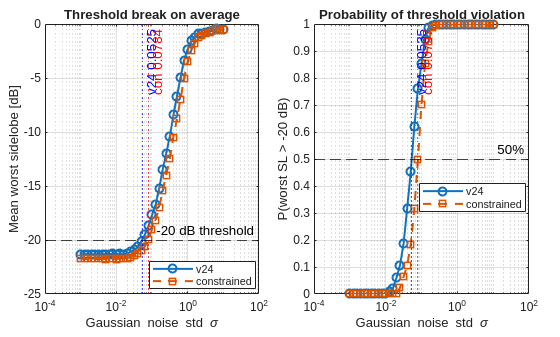


figure('Name', 'Processing error comparison: v24 vs constrained', 'Color', 'w');
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
semilogx(err_v24.sigma_list, err_v24.mean_ws, '-o', 'LineWidth', 1.5);
hold on;
semilogx(err_constrained.sigma_list, err_constrained.mean_ws, '--s', 'LineWidth', 1.5);
yline(proc_threshold_dB, 'k--', sprintf('%.0f dB threshold', proc_threshold_dB));

if ~isnan(err_v24.sigma_break)
    xline(err_v24.sigma_break, 'b:', ...
        sprintf('v24 %.3g', err_v24.sigma_break));
end

if ~isnan(err_constrained.sigma_break)
    xline(err_constrained.sigma_break, 'r:', ...
        sprintf('con %.3g', err_constrained.sigma_break));
end

grid on;
xlabel('Gaussian noise std \sigma');
ylabel('Mean worst sidelobe [dB]');
title('Threshold break on average');
legend({'v24', 'constrained'}, 'Location', 'best');

nexttile;
semilogx(err_v24.sigma_list, err_v24.pct_break, '-o', 'LineWidth', 1.5);
hold on;
semilogx(err_constrained.sigma_list, err_constrained.pct_break, '--s', 'LineWidth', 1.5);
yline(0.5, 'k--', '50%');

if ~isnan(err_v24.sigma_50pct)
    xline(err_v24.sigma_50pct, 'b:', ...
        sprintf('v24 %.3g', err_v24.sigma_50pct));
end

if ~isnan(err_constrained.sigma_50pct)
    xline(err_constrained.sigma_50pct, 'r:', ...
        sprintf('con %.3g', err_constrained.sigma_50pct));
end

grid on;
xlabel('Gaussian noise std \sigma');
ylabel(sprintf('P(worst SL > %.0f dB)', proc_threshold_dB));
ylim([0 1]);
title('Probability of threshold violation');
legend({'v24', 'constrained'}, 'Location', 'best');


fprintf('\n=== Processing error comparison ===\n');


=== Processing error comparison ===


fprintf('Trials per sigma = %d\n', n_trials_proc);

Trials per sigma = 300



fprintf(['  v24:         noiseless WS = %.2f dB,  ' ...
         'mean-break sigma = %.4g,  50%%-break sigma = %.4g\n'], ...
    err_v24.ref_ws_dB, ...
    err_v24.sigma_break, ...
    err_v24.sigma_50pct);

  v24:         noiseless WS = -21.31 dB,  mean-break sigma = 0.05253,  50%-break sigma = 0.05346



fprintf(['  constrained: noiseless WS = %.2f dB,  ' ...
         'mean-break sigma = %.4g,  50%%-break sigma = %.4g\n'], ...
    err_constrained.ref_ws_dB, ...
    err_constrained.sigma_break, ...
    err_constrained.sigma_50pct);

  constrained: noiseless WS = -21.76 dB,  mean-break sigma = 0.07844,  50%-break sigma = 0.07973


## Numerical comparison: v24 vs constrained

Side-by-side numerical breakdown for the two methods. All dB values are referenced to the constrained pattern's peak (so constrained's "Peak dB" is 0 by construction).

fprintf('\n========== v24 vs constrained ==========\n');


========== v24 vs constrained ==========


fprintf('Reference = constrained pattern peak = %.6g\n', peak_ref);

Reference = constrained pattern peak = 9.00328


fprintf('Intended phi_0 = %.4f deg\n\n', rad2deg(phi_0));

Intended phi_0 = 180.0000 deg



fprintf('                                v24                constrained\n');

                                v24                constrained


fprintf('  -----------------------------------------------------------------\n');

  -----------------------------------------------------------------


fprintf('  Peak |F|                %12.6g       %12.6g\n', v24_max_val, con_max_val);

  Peak |F|                     6.92749            9.00328


fprintf('  Peak angle (deg)        %12.4f       %12.4f\n', rad2deg(v24_max_phi), rad2deg(con_max_phi));

  Peak angle (deg)            179.2800           179.2800


fprintf('  Peak dB (rel ref)       %+12.3f       %+12.3f\n', v24_max_dB,  con_max_dB);

  Peak dB (rel ref)             -2.276             +0.000


fprintf('  |F| at phi_0            %12.6g       %12.6g\n', F_v24_phi0,  F_con_phi0);

  |F| at phi_0                 6.92482                  9


fprintf('  dB at phi_0 (rel ref)   %+12.3f       %+12.3f\n', v24_phi0_dB, con_phi0_dB);

  dB at phi_0 (rel ref)         -2.280             -0.003


fprintf('  Worst sidelobe (dB ref) %+12.3f       %+12.3f\n', v24_sl_dB,   con_sl_dB);

  Worst sidelobe (dB ref)      -23.587            -21.755


fprintf('  Worst SL angle (deg)    %12.4f       %12.4f\n', rad2deg(v24_sl_phi), rad2deg(con_sl_phi));

  Worst SL angle (deg)         38.5200             0.7200


fprintf('  Iterations              %12d       %12d\n',  res_v24.final_iteration, res_con.final_iteration);

  Iterations                         5                  6


fprintf('  Time (s)                %12.3f       %12.3f\n', t_v24, t_con);

  Time (s)                       0.015              0.040


fprintf('  -----------------------------------------------------------------\n');

  -----------------------------------------------------------------


fprintf('  rel-err (vs constrained) = %.3e\n', err_methods);

  rel-err (vs constrained) = 2.325e-01


fprintf('  Speed ratio (con/v24)    = %.2fx\n', t_con / max(t_v24, eps));

  Speed ratio (con/v24)    = 2.78x


## Focus angle sweep (movies)

Sweeps the focus direction phi_0 from 0 to 359 in 1-degree steps. At each angle the chosen method is run to convergence and only its FINAL pattern is captured. Two movies are written (one per method) and saved to the current working directory by default. Each frame shows the final polar pattern for that angle plus a green radial line at the intended phi_0. Set save_movie=false in the function call if you only want the data and no file output.

% --- v24 sweep + movie ---
sweep_v24 = focus_angle_sweep( ...
    'method',          'v24', ...
    'N',               N, ...
    'd_ideal',         d1, ...
    'Max_iter',        Max_iter, ...
    'eps_dB',          eps_dB, ...
    'cone_rad',        cone_rad, ...
    'fast_peaks',      fast_peaks, ...
    'angle_deg_list',  0:1:359, ...
    'save_movie',      true, ...
    'frame_rate',      30, ...
    'show_progress',   true);

focus_angle_sweep: method=v24, 360 angles, fast_peaks=1
   30/360  phi_0= 29 deg   t=0.002s   total=0.1s
   60/360  phi_0= 59 deg   t=0.002s   total=0.2s
   90/360  phi_0= 89 deg   t=0.002s   total=0.2s
  120/360  phi_0=119 deg   t=0.002s   total=0.4s
  150/360  phi_0=149 deg   t=0.005s   total=0.5s
  180/360  phi_0=179 deg   t=0.007s   total=0.8s
  210/360  phi_0=209 deg   t=0.004s   total=0.9s
  240/360  phi_0=239 deg   t=0.002s   total=1.0s
  270/360  phi_0=269 deg   t=0.004s   total=1.1s
  300/360  phi_0=299 deg   t=0.002s   total=1.2s
  330/360  phi_0=329 deg   t=0.002s   total=1.3s
  360/360  phi_0=359 deg   t=0.006s   total=1.4s
Sweep complete in 1.4 s.  Mean per-angle = 0.004 s.
Writing movie: focus_sweep_v24.avi  (360 frames @ 30 fps, profile=Motion JPEG AVI)


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written
  frame 300/360 written
  frame 360/360 written
Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_v24.avi



% --- constrained sweep + movie ---
sweep_con = focus_angle_sweep( ...
    'method',           'constrained', ...
    'N',                N, ...
    'd_ideal',          d1, ...
    'Max_iter',         Max_iter, ...
    'eps_dB',           eps_dB, ...
    'cone_rad',         cone_rad, ...
    'max_outer_passes', max_outer_passes, ...
    'fast_peaks',       fast_peaks, ...
    'angle_deg_list',   0:1:359, ...
    'save_movie',       true, ...
    'frame_rate',       30, ...
    'show_progress',    true);

focus_angle_sweep: method=constrained, 360 angles, fast_peaks=1
   30/360  phi_0= 29 deg   t=0.014s   total=0.6s
   60/360  phi_0= 59 deg   t=0.016s   total=1.1s
   90/360  phi_0= 89 deg   t=0.071s   total=1.9s
  120/360  phi_0=119 deg   t=0.003s   total=2.3s
  150/360  phi_0=149 deg   t=0.004s   total=2.5s
  180/360  phi_0=179 deg   t=0.008s   total=3.0s
  210/360  phi_0=209 deg   t=0.026s   total=3.5s
  240/360  phi_0=239 deg   t=0.005s   total=3.8s
  270/360  phi_0=269 deg   t=0.011s   total=4.2s
  300/360  phi_0=299 deg   t=0.005s   total=4.7s
  330/360  phi_0=329 deg   t=0.015s   total=5.1s
  360/360  phi_0=359 deg   t=0.009s   total=5.5s
Sweep complete in 5.5 s.  Mean per-angle = 0.015 s.
Writing movie: focus_sweep_constrained.avi  (360 frames @ 30 fps, profile=Motion JPEG AVI)


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written


  frame 300/360 written


  frame 360/360 written
Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_constrained.avi



fprintf('\n=== Focus sweep summary ===\n');


=== Focus sweep summary ===


fprintf('v24:         total %.1fs over %d angles  (mean %.3fs/angle)\n', ...
    sum(sweep_v24.times), numel(sweep_v24.angles_deg), mean(sweep_v24.times));

v24:         total 1.3s over 360 angles  (mean 0.004s/angle)


if ~isempty(sweep_v24.movie_file)
    fprintf('  movie: %s\n', sweep_v24.movie_file);
end

  movie: /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_v24.avi


fprintf('constrained: total %.1fs over %d angles  (mean %.3fs/angle)\n', ...
    sum(sweep_con.times), numel(sweep_con.angles_deg), mean(sweep_con.times));

constrained: total 5.4s over 360 angles  (mean 0.015s/angle)


if ~isempty(sweep_con.movie_file)
    fprintf('  movie: %s\n', sweep_con.movie_file);
end

  movie: /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_constrained.avi


## Advanced 2-beam focus sweep (movies)

Sweeps the FIRST focus phi_1 from 0 to 359 in 1-degree steps while keeping the SECOND focus phi_2 = mod(phi_1 + sep, 2*pi). One movie is produced per separation in sep_list_deg. The 2-beam pattern is mirror-symmetric across sep 

% Advanced 2-beam focus sweep (movies)
% Sweeps the FIRST focus phi_1 from 0 to 359 deg while keeping
% phi_2 = mod(phi_1 + sep, 2*pi). One movie is written per separation.

sep_list_deg  = [30, 60, 90, 120, 180];   % choose any separations in (0,180]
phi_sweep_deg = 0:1:359;
phi_sweep_rad = deg2rad(phi_sweep_deg);

nA            = numel(phi_sweep_deg);
clip_dB_movie = -40;
frame_rate_2b = 30;
cone_rad_2b   = deg2rad(15);

% Must match the method's internal phi mesh
Mphi        = 1000;
phi_mesh_2b = linspace(0, 2*pi, Mphi + 1);
phi_mesh_2b(end) = [];

% Movie format by platform
if ispc || ismac
    movie_ext     = '.mp4';
    movie_profile = 'MPEG-4';
else
    movie_ext     = '.avi';
    movie_profile = 'Motion JPEG AVI';
end

for ii = 1:numel(sep_list_deg)
    sep_deg = sep_list_deg(ii);
    sep_rad = deg2rad(sep_deg);

    fprintf('\n--- Advanced 2-beam sweep: sep = %g deg ---\n', sep_deg);

    F_all  = zeros(nA, Mphi);
    times  = zeros(nA, 1);
    phi2_d = zeros(nA, 1);

    % Step 1: run perturb_method_2_beam_v5 at every focus angle
    t_total = tic;

    for k = 1:nA
        phi_1 = phi_sweep_rad(k);
        phi_2 = mod(phi_1 + sep_rad, 2*pi);
        phi2_d(k) = round(rad2deg(phi_2));

        tic_k = tic;

        r = perturb_method_2_beam_v5(x, y, phi_1, phi_2, ...
            'Max_iter',        Max_iter, ...
            'eps_dB',          eps_dB, ...
            'cone_rad',        cone_rad_2b, ...
            'fast_peaks',      fast_peaks, ...
            'verbose',         false, ...
            'show_plots',      false, ...
            'show_final_plot', false, ...
            'return_funcs',    false);

        times(k) = toc(tic_k);

        % If final_function is complex field, use abs(...). If already
        % magnitude, abs(...) is harmless.
        F_all(k, :) = abs(r.final_function);

        if mod(k, 30) == 0 || k == nA
            fprintf('  %3d/%3d  phi_1=%3d  phi_2=%3d  t=%.3fs  total=%.1fs\n', ...
                k, nA, phi_sweep_deg(k), phi2_d(k), times(k), toc(t_total));
        end
    end

    fprintf('Sweep complete in %.1f s. Mean per-angle = %.3f s.\n', ...
        toc(t_total), mean(times));

    % Step 2: assemble movie
    filename = sprintf('focus_sweep_2beam_sep%03d%s', round(sep_deg), movie_ext);
    fprintf('Writing movie: %s\n', filename);

    fig = figure( ...
        'Name',     sprintf('2-beam sweep: sep=%g deg', sep_deg), ...
        'Color',    'w', ...
        'Position', [100 100 720 720], ...
        'Visible',  'on');

    pax = polaraxes(fig);
    hold(pax, 'on');

    v = VideoWriter(filename, movie_profile);
    v.FrameRate = frame_rate_2b;
    open(v);

    aborted = false;

    for k = 1:nA
        phi_1 = phi_sweep_rad(k);
        phi_2 = mod(phi_1 + sep_rad, 2*pi);

        Fmag = F_all(k, :);
        F_dB = max(10*log10((Fmag.^2) / max(Fmag)^2), clip_dB_movie);

        cla(pax);

        polarplot(pax, phi_mesh_2b, F_dB, 'b-', 'LineWidth', 1.5);
        hold(pax, 'on');

        polarplot(pax, [phi_1 phi_1], [clip_dB_movie 0], 'g-', 'LineWidth', 1.5);
        polarplot(pax, [phi_2 phi_2], [clip_dB_movie 0], 'm-', 'LineWidth', 1.5);

        rlim(pax, [clip_dB_movie 0]);

        title(pax, sprintf(['2-beam | sep=%g deg | ', ...
            '\\phi_1=%3d deg | \\phi_2=%3d deg | t=%.3fs'], ...
            sep_deg, phi_sweep_deg(k), round(rad2deg(phi_2)), times(k)));

        drawnow limitrate;

        try
            frame_img = print(fig, '-RGBImage', '-r0');
            writeVideo(v, frame_img);
        catch ME
            warning('focus_sweep_2beam:frame_fail', ...
                'Frame %d failed: %s. Aborting movie write.', k, ME.message);
            aborted = true;
            break;
        end

        if mod(k, 60) == 0 || k == nA
            fprintf('  frame %3d/%3d written\n', k, nA);
        end
    end

    try
        close(v);
    catch
    end

    try
        if isgraphics(fig)
            close(fig);
        end
    catch
    end

    if aborted
        try
            if exist(filename, 'file')
                delete(filename);
            end
        catch
        end
    else
        fprintf('Saved movie to %s\n', fullfile(pwd, filename));
    end
end


--- Advanced 2-beam sweep: sep = 30 deg ---


   30/360  phi_1= 29  phi_2= 59  t=0.002s  total=0.3s
   60/360  phi_1= 59  phi_2= 89  t=0.003s  total=0.4s
   90/360  phi_1= 89  phi_2=119  t=0.002s  total=0.5s
  120/360  phi_1=119  phi_2=149  t=0.002s  total=0.6s
  150/360  phi_1=149  phi_2=179  t=0.006s  total=0.7s
  180/360  phi_1=179  phi_2=209  t=0.007s  total=0.8s
  210/360  phi_1=209  phi_2=239  t=0.006s  total=1.0s
  240/360  phi_1=239  phi_2=269  t=0.004s  total=1.2s
  270/360  phi_1=269  phi_2=299  t=0.008s  total=1.5s
  300/360  phi_1=299  phi_2=329  t=0.002s  total=1.7s
  330/360  phi_1=329  phi_2=359  t=0.005s  total=1.8s
  360/360  phi_1=359  phi_2= 29  t=0.017s  total=1.9s


Sweep complete in 1.9 s. Mean per-angle = 0.005 s.


Writing movie: focus_sweep_2beam_sep030.avi


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written
  frame 300/360 written
  frame 360/360 written


Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_2beam_sep030.avi



--- Advanced 2-beam sweep: sep = 60 deg ---


   30/360  phi_1= 29  phi_2= 89  t=0.004s  total=0.2s
   60/360  phi_1= 59  phi_2=119  t=0.007s  total=0.4s
   90/360  phi_1= 89  phi_2=149  t=0.002s  total=0.5s
  120/360  phi_1=119  phi_2=179  t=0.002s  total=0.6s
  150/360  phi_1=149  phi_2=209  t=0.001s  total=0.7s
  180/360  phi_1=179  phi_2=239  t=0.004s  total=0.8s
  210/360  phi_1=209  phi_2=269  t=0.001s  total=1.1s
  240/360  phi_1=239  phi_2=299  t=0.001s  total=1.2s
  270/360  phi_1=269  phi_2=329  t=0.001s  total=1.3s
  300/360  phi_1=299  phi_2=359  t=0.025s  total=1.5s
  330/360  phi_1=329  phi_2= 29  t=0.001s  total=1.6s
  360/360  phi_1=359  phi_2= 59  t=0.001s  total=1.7s


Sweep complete in 1.7 s. Mean per-angle = 0.004 s.


Writing movie: focus_sweep_2beam_sep060.avi


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written
  frame 300/360 written
  frame 360/360 written


Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_2beam_sep060.avi



--- Advanced 2-beam sweep: sep = 90 deg ---


   30/360  phi_1= 29  phi_2=119  t=0.002s  total=0.2s
   60/360  phi_1= 59  phi_2=149  t=0.006s  total=0.3s
   90/360  phi_1= 89  phi_2=179  t=0.005s  total=0.4s
  120/360  phi_1=119  phi_2=209  t=0.003s  total=0.6s
  150/360  phi_1=149  phi_2=239  t=0.003s  total=0.8s
  180/360  phi_1=179  phi_2=269  t=0.002s  total=0.9s
  210/360  phi_1=209  phi_2=299  t=0.006s  total=1.0s
  240/360  phi_1=239  phi_2=329  t=0.003s  total=1.3s
  270/360  phi_1=269  phi_2=359  t=0.005s  total=1.5s
  300/360  phi_1=299  phi_2= 29  t=0.013s  total=1.7s
  330/360  phi_1=329  phi_2= 59  t=0.002s  total=1.9s
  360/360  phi_1=359  phi_2= 89  t=0.001s  total=2.1s


Sweep complete in 2.1 s. Mean per-angle = 0.006 s.


Writing movie: focus_sweep_2beam_sep090.avi


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written
  frame 300/360 written
  frame 360/360 written


Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_2beam_sep090.avi



--- Advanced 2-beam sweep: sep = 120 deg ---


   30/360  phi_1= 29  phi_2=149  t=0.005s  total=0.1s
   60/360  phi_1= 59  phi_2=179  t=0.004s  total=0.3s
   90/360  phi_1= 89  phi_2=209  t=0.016s  total=0.4s
  120/360  phi_1=119  phi_2=239  t=0.007s  total=0.7s
  150/360  phi_1=149  phi_2=269  t=0.005s  total=0.8s
  180/360  phi_1=179  phi_2=299  t=0.004s  total=1.1s
  210/360  phi_1=209  phi_2=329  t=0.002s  total=1.3s
  240/360  phi_1=239  phi_2=359  t=0.003s  total=1.4s
  270/360  phi_1=269  phi_2= 29  t=0.002s  total=1.5s
  300/360  phi_1=299  phi_2= 59  t=0.004s  total=1.7s
  330/360  phi_1=329  phi_2= 89  t=0.002s  total=1.8s
  360/360  phi_1=359  phi_2=119  t=0.003s  total=1.9s


Sweep complete in 2.0 s. Mean per-angle = 0.005 s.


Writing movie: focus_sweep_2beam_sep120.avi


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written
  frame 300/360 written
  frame 360/360 written


Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_2beam_sep120.avi



--- Advanced 2-beam sweep: sep = 180 deg ---


   30/360  phi_1= 29  phi_2=209  t=0.002s  total=0.2s
   60/360  phi_1= 59  phi_2=239  t=0.002s  total=0.3s
   90/360  phi_1= 89  phi_2=269  t=0.002s  total=0.5s
  120/360  phi_1=119  phi_2=299  t=0.002s  total=0.6s
  150/360  phi_1=149  phi_2=329  t=0.008s  total=0.7s
  180/360  phi_1=179  phi_2=359  t=0.010s  total=0.9s
  210/360  phi_1=209  phi_2= 29  t=0.002s  total=1.1s
  240/360  phi_1=239  phi_2= 59  t=0.001s  total=1.2s
  270/360  phi_1=269  phi_2= 89  t=0.005s  total=1.3s
  300/360  phi_1=299  phi_2=119  t=0.003s  total=1.5s
  330/360  phi_1=329  phi_2=149  t=0.002s  total=1.6s
  360/360  phi_1=359  phi_2=179  t=0.005s  total=1.7s


Sweep complete in 1.7 s. Mean per-angle = 0.004 s.


Writing movie: focus_sweep_2beam_sep180.avi


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written


  frame 240/360 written
  frame 300/360 written
  frame 360/360 written


Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_2beam_sep180.avi



fprintf('\n=== Advanced 2-beam sweeps complete ===\n');


=== Advanced 2-beam sweeps complete ===


## 1 Beam and 1 Null Method

 % 1-beam / 1-null focus sweep (movies)
  % Sweeps the main beam phi_0 from 0 to 359 deg while keeping
  % null_phi = mod(phi_0 + sep, 2*pi). One movie is written per separation.

  sep_list_deg  = [30, 60, 90, 120, 180];
  phi_sweep_deg = 0:1:359;
  phi_sweep_rad = deg2rad(phi_sweep_deg);

  nA            = numel(phi_sweep_deg);
  clip_dB_movie = -40;
  frame_rate_1n = 30;

  % Must match perturb_method_v24 internal phi mesh
  Mphi        = 1000;
  phi_mesh_1n = linspace(0, 2*pi, Mphi+1);
  phi_mesh_1n(end) = [];

  % Movie format by platform
  if ispc || ismac
      movie_ext     = '.mp4';
      movie_profile = 'MPEG-4';
  else
      movie_ext     = '.avi';
      movie_profile = 'Motion JPEG AVI';
  end

  for ii = 1:numel(sep_list_deg)
      sep_deg = sep_list_deg(ii);
      sep_rad = deg2rad(sep_deg);

      fprintf('\n--- 1-beam / 1-null sweep: sep = %g deg ---\n', sep_deg);

      F_all   = zeros(nA, Mphi);
      times   = zeros(nA, 1);
      null_d  = zeros(nA, 1);

      % Step 1: run perturb_method_v24 at every beam angle
      t_total = tic;
      for k = 1:nA
          phi_0    = phi_sweep_rad(k);
          null_phi = mod(phi_0 + sep_rad, 2*pi);
          null_d(k) = round(rad2deg(null_phi));

          tic_k = tic;
          r = perturb_method_v24(Max_iter, eps_dB, x, y, phi_0, ...
              'null_phi',        null_phi, ...
              'fast_peaks',      fast_peaks, ...
              'verbose',         false, ...
              'show_plots',      false, ...
              'show_final_plot', false, ...
              'return_funcs',    false);

          times(k) = toc(tic_k);
          F_all(k,:) = abs(r.final_function);

          if mod(k, 30) == 0 || k == nA
              fprintf('  %3d/%3d  beam=%3d  null=%3d  t=%.3fs  total=%.1fs\n', ...
                  k, nA, phi_sweep_deg(k), null_d(k), times(k), toc(t_total));
          end
      end

      fprintf('Sweep complete in %.1f s. Mean per-angle = %.3f s.\n', ...
          toc(t_total), mean(times));

      % Step 2: assemble movie
      filename = sprintf('focus_sweep_1beam_1null_sep%03d%s', round(sep_deg), movie_ext);
      fprintf('Writing movie: %s\n', filename);

      fig = figure('Name', sprintf('1-beam / 1-null sweep: sep=%g deg', sep_deg), ...
          'Color', 'w', 'Position', [100 100 720 720], 'Visible', 'on');
      pax = polaraxes(fig);
      hold(pax, 'on');

      v = VideoWriter(filename, movie_profile);
      v.FrameRate = frame_rate_1n;
      open(v);

      aborted = false;

      for k = 1:nA
          phi_0    = phi_sweep_rad(k);
          null_phi = mod(phi_0 + sep_rad, 2*pi);

          Fmag = F_all(k,:);
          F_dB = max(10*log10((Fmag.^2) / max(Fmag).^2), clip_dB_movie);

          cla(pax);
          polarplot(pax, phi_mesh_1n, F_dB, 'b-', 'LineWidth', 1.5); hold(pax, 'on');
          polarplot(pax, [phi_0 phi_0], [clip_dB_movie 0], 'g-', 'LineWidth', 1.5);
          polarplot(pax, [null_phi null_phi], [clip_dB_movie 0], 'm-', 'LineWidth', 1.5);
          rlim(pax, [clip_dB_movie 0]);

          title(pax, sprintf(['1-beam / 1-null | sep=%g deg | ', ...
              '\\phi_0=%3d deg | null=%3d deg | t=%.3fs'], ...
              sep_deg, phi_sweep_deg(k), round(rad2deg(null_phi)), times(k)));

          drawnow limitrate;

          try
              frame_img = print(fig, '-RGBImage', '-r0');
              writeVideo(v, frame_img);
          catch ME
              warning('focus_sweep_1beam_1null:frame_fail', ...
                  'Frame %d failed: %s. Aborting movie write.', k, ME.message);
              aborted = true;
              break;
          end

          if mod(k, 60) == 0 || k == nA
              fprintf('  frame %3d/%3d written\n', k, nA);
          end
      end

      try
          close(v);
      catch
      end

      try
          if isgraphics(fig)
              close(fig);
          end
      catch
      end

      if aborted
          try
              if exist(filename, 'file')
                  delete(filename);
              end
          catch
          end
      else
          fprintf('Saved movie to %s\n', fullfile(pwd, filename));
      end
  end


--- 1-beam / 1-null sweep: sep = 30 deg ---


   30/360  beam= 29  null= 59  t=0.004s  total=0.2s
   60/360  beam= 59  null= 89  t=0.011s  total=0.5s
   90/360  beam= 89  null=119  t=0.010s  total=0.9s
  120/360  beam=119  null=149  t=0.005s  total=1.3s
  150/360  beam=149  null=179  t=0.010s  total=1.5s
  180/360  beam=179  null=209  t=0.013s  total=1.7s
  210/360  beam=209  null=239  t=0.005s  total=1.9s
  240/360  beam=239  null=269  t=0.005s  total=2.1s
  270/360  beam=269  null=299  t=0.008s  total=2.3s
  300/360  beam=299  null=329  t=0.005s  total=2.6s
  330/360  beam=329  null=359  t=0.004s  total=2.7s
  360/360  beam=359  null= 29  t=0.015s  total=3.0s


Sweep complete in 3.0 s. Mean per-angle = 0.008 s.


Writing movie: focus_sweep_1beam_1null_sep030.avi


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written
  frame 300/360 written
  frame 360/360 written


Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_1beam_1null_sep030.avi



--- 1-beam / 1-null sweep: sep = 60 deg ---


   30/360  beam= 29  null= 89  t=0.006s  total=0.3s
   60/360  beam= 59  null=119  t=0.009s  total=0.6s
   90/360  beam= 89  null=149  t=0.013s  total=0.9s
  120/360  beam=119  null=179  t=0.011s  total=1.2s
  150/360  beam=149  null=209  t=0.017s  total=1.7s
  180/360  beam=179  null=239  t=0.019s  total=1.9s
  210/360  beam=209  null=269  t=0.004s  total=2.0s
  240/360  beam=239  null=299  t=0.003s  total=2.2s
  270/360  beam=269  null=329  t=0.006s  total=2.4s
  300/360  beam=299  null=359  t=0.005s  total=2.6s
  330/360  beam=329  null= 29  t=0.002s  total=2.8s
  360/360  beam=359  null= 59  t=0.006s  total=3.1s


Sweep complete in 3.1 s. Mean per-angle = 0.008 s.


Writing movie: focus_sweep_1beam_1null_sep060.avi


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written


  frame 300/360 written
  frame 360/360 written


Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_1beam_1null_sep060.avi



--- 1-beam / 1-null sweep: sep = 90 deg ---


   30/360  beam= 29  null=119  t=0.019s  total=0.3s
   60/360  beam= 59  null=149  t=0.004s  total=0.6s
   90/360  beam= 89  null=179  t=0.003s  total=0.8s
  120/360  beam=119  null=209  t=0.006s  total=1.1s
  150/360  beam=149  null=239  t=0.004s  total=1.3s
  180/360  beam=179  null=269  t=0.004s  total=1.5s
  210/360  beam=209  null=299  t=0.007s  total=1.9s
  240/360  beam=239  null=329  t=0.005s  total=2.1s
  270/360  beam=269  null=359  t=0.017s  total=2.5s
  300/360  beam=299  null= 29  t=0.006s  total=2.9s
  330/360  beam=329  null= 59  t=0.015s  total=3.2s
  360/360  beam=359  null= 89  t=0.003s  total=3.6s


Sweep complete in 3.6 s. Mean per-angle = 0.010 s.


Writing movie: focus_sweep_1beam_1null_sep090.avi


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written
  frame 300/360 written
  frame 360/360 written


Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_1beam_1null_sep090.avi



--- 1-beam / 1-null sweep: sep = 120 deg ---


   30/360  beam= 29  null=149  t=0.012s  total=0.2s
   60/360  beam= 59  null=179  t=0.007s  total=0.4s
   90/360  beam= 89  null=209  t=0.008s  total=0.7s
  120/360  beam=119  null=239  t=0.005s  total=0.9s
  150/360  beam=149  null=269  t=0.006s  total=1.1s
  180/360  beam=179  null=299  t=0.005s  total=1.2s
  210/360  beam=209  null=329  t=0.003s  total=1.3s
  240/360  beam=239  null=359  t=0.003s  total=1.5s
  270/360  beam=269  null= 29  t=0.015s  total=1.7s
  300/360  beam=299  null= 59  t=0.010s  total=1.9s
  330/360  beam=329  null= 89  t=0.008s  total=2.1s
  360/360  beam=359  null=119  t=0.010s  total=2.2s


Sweep complete in 2.2 s. Mean per-angle = 0.006 s.


Writing movie: focus_sweep_1beam_1null_sep120.avi


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written
  frame 300/360 written
  frame 360/360 written


Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_1beam_1null_sep120.avi



--- 1-beam / 1-null sweep: sep = 180 deg ---


   30/360  beam= 29  null=209  t=0.011s  total=0.3s
   60/360  beam= 59  null=239  t=0.002s  total=0.7s
   90/360  beam= 89  null=269  t=0.006s  total=0.9s
  120/360  beam=119  null=299  t=0.003s  total=1.1s
  150/360  beam=149  null=329  t=0.003s  total=1.4s
  180/360  beam=179  null=359  t=0.030s  total=1.8s
  210/360  beam=209  null= 29  t=0.003s  total=2.1s
  240/360  beam=239  null= 59  t=0.005s  total=2.5s
  270/360  beam=269  null= 89  t=0.013s  total=2.8s
  300/360  beam=299  null=119  t=0.004s  total=3.2s
  330/360  beam=329  null=149  t=0.012s  total=3.5s
  360/360  beam=359  null=179  t=0.002s  total=3.7s


Sweep complete in 3.7 s. Mean per-angle = 0.010 s.


Writing movie: focus_sweep_1beam_1null_sep180.avi


  frame  60/360 written
  frame 120/360 written
  frame 180/360 written
  frame 240/360 written
  frame 300/360 written
  frame 360/360 written


Saved movie to /home/dusty/Desktop/Matlab_UH_Project/Proof/Matlab_Code/focus_sweep_1beam_1null_sep180.avi



  fprintf('\n=== 1-beam / 1-null sweeps complete ===\n');


=== 1-beam / 1-null sweeps complete ===
